# Making maps using shapfiles

Shapefiles describe plots of land using a data type called a *mappolyshape*. We can plot shapefiles in MATLAB by reading them in using the `readgeotable()` function and passing the resulting table into `geoplot()`.

## The `geoplot()` function.

The `geoplot()` function plots data on maps from a variety of map inputs.  Calling `geoplot()` with different types of input data causes it to create different types of plots.

For example, you've learned that geoplot() takes a longitude and lattitude and will plot a marker on that point in the world.  You use regular graphing options to control the marker's shape and color.

### The` geoplot(`[`geospacial table`](https://www.mathworks.com/help/map/create-geospatial-tables.html)`) `function

The internet is full of *shape files* that contain shapes placed on longitude and lattitude.  You import these files uisng `readgeotable()` and plot the resulting table.

Here, we import a shape file of Natick property parcels:

natick = readgeotable("L3_SHP_M198_Natick/M198TaxPar_CY24_FY25.shp");
natick(1:3,{'Shape' 'SHAPE_Leng' 'SHAPE_Area'})

ans = 3x3 table
       Shape        SHAPE_Leng    SHAPE_Area
    ____________    __________    __________

    mappolyshape      159.22        1438.3  
    mappolyshape      85.769        370.54  
    mappolyshape      32.637        28.456  


We see above that the *geospacial table* we imported has a variable named `Shape`.  `geoplot()` needs the table to contain a `Shape` variable to find the shapes to plot.  The `Shape` variable needs to be of type `mappolyshape` for `geoplot()` to be able to plot it.

Now that we have a goespacial table, we can plot it and see Natick High School.

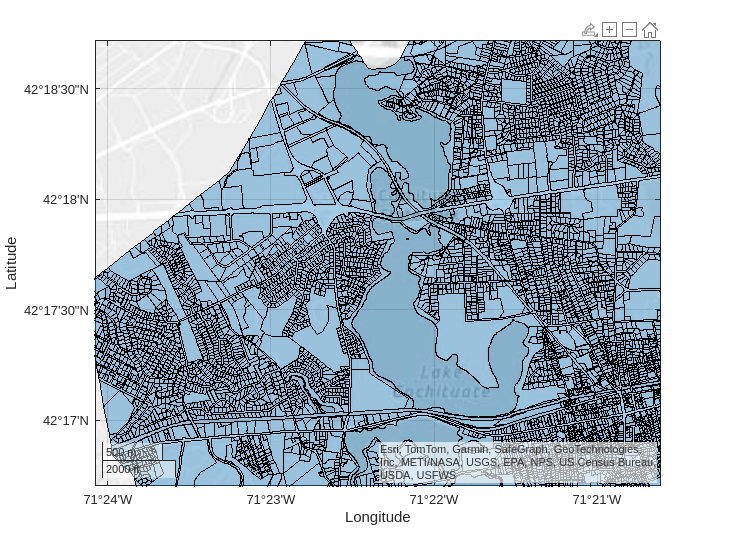

geoplot(natick)
geolimits([42.2680 42.2789],[-71.37276 -71.35407])